# Demo: Green's Functions in 2D Acoustics

This live-script features the following:

- 2D example

- generates and validates the Green's function for this problem

Here we consider acoustic pressure data 


$$d = \{ p(x_r,y_r,t), \; 0\le t \le T\}$$
   

for a single ***receiver location*** $(x_r,y_r)$, where the pressure field $p$ satisfies the 2D acoustic equations:


$$\frac{\partial p}{\partial t} + \kappa \left( \frac{\partial v_x}{\partial x} + \frac{\partial v_y}{\partial y} \right) = w(t)\delta(x-x_c)\delta(y-y_c)$$



$$\frac{\partial v_x}{\partial t} + \beta \frac{\partial p}{\partial x} = 0 ,\ \ \ \frac{\partial v_y}{\partial t} + \beta \frac{\partial p}{\partial y} = 0 , $$


Given source time function $w(t)$, the resulting pressure data can be generated by using a Green's function,


$$p(x_r,y_r,t) = G^p(x_r,y_r,t)* w(t)$$


where $*$ denotes time convolution and $G^p$ is the pressure field Green's function satisfying


$$\frac{\partial G^p}{\partial t} + \kappa \left( \frac{\partial G^{v_x}}{\partial x} + \frac{\partial G^{v_y}}{\partial y} \right) = \delta(t)\delta(x-x_c)\delta(y-y_c)$$



$$\frac{\partial G^{v_x}}{\delta t} + \beta \frac{\partial G^p}{\partial x} = 0,\ \ \ \frac{\partial G^{v_y}}{\partial t} + \beta \frac{\partial G^p}{\partial y} = 0 , $$


 with the same initial and boundary conditions as in the original problem.

## Initial set up

clear

t_final = 1;
domain_t = [0,t_final];
domain_x = [0,1];
domain_y = [0,1.2];

% Initial conditions
p0 = @(x,y) zeros(size(x));
vx0 = @(x,y) zeros(size(x));
vy0 = @(x,y) zeros(size(x));

% Initializing PML
pml = PML2D(WidthLeft=0.2,WidthRight=0.2,WidthBottom=0.2,WidthTop=0.2);

% Single point receiver
x_rcv = 0.2;
y_rcv = 0.5;
grid_x_pt = Grid1D(domain_x,x_rcv);
grid_y_pt = Grid1D(domain_y,y_rcv);
gridSp_rcv = GridSpace2D(grid_x_pt,grid_y_pt);

% Continuous acoustic medium object function
% medium = AcousticMedium1D.layered( ...
%     BetaValues=[0.25,0.5,1], ...
%     KappaValues=[4,3,6], ...
%     Domain=domain_x, ...
%     RelativeWidths=[0.5,0.3,0.2]);
medium = AcousticMedium2D.constant(BetaValue=1,KappaValue=1);

## Computing pressure data directly

The time interval over which pressure data is computed is $[0,T]$.

As usual, we discretize the time domain by introducing a uniform grid with grid size $\Delta_t$ in such a way the required CFL condition is satisfied. We refer to the resulting time grid as the ***computational time grid***.

% Spatial computational grids and grid spaces
Nx=201;
Ny=211;
grid_x_primal = Grid1DUnifPrimal(domain_x,Nx);
grid_y_primal = Grid1DUnifPrimal(domain_y,Ny);
grid_x_dual   = Grid1DUnifDual(grid_x_primal);
grid_y_dual   = Grid1DUnifDual(grid_y_primal);

gridSp_P = GridSpace2D(grid_x_primal, grid_y_primal);   %grid space for pressure
gridSp_Vx = GridSpace2D(grid_x_dual,  grid_y_primal);   %grid spaces for velocity in x
gridSp_Vy = GridSpace2D(grid_x_primal,  grid_y_dual);   %grid spaces for velocity in y

h = gridSp_P.h; %spatial grid sizes, h = [dx,dy]

% Sampling medium parameters to compute max wave speed 
[~,~,~,wspeed,cMax] = sampleMedium2D(gridSp_P,medium);

% Determining computational time grid size
CFL_factor = 0.8;
dt_cmp = CFL_factor*(6/7)/(cMax*sqrt(sum(1./h.^2))); %CFL condition for 2-4 FDM
Nt_cmp = ceil(diff(domain_t)/dt_cmp)+1;
dt_cmp = diff(domain_t)/(Nt_cmp-1); %recomputing to ensure time domain divisible by dt

% Computational time points
t_cmp = domain_t(1):dt_cmp:domain_t(2);

In practice, the pressure data is sampled/stored on a uniform time grid that is much coarser than the computational grid. This results in a time series vector for the pressure data, $\mathbf d\in\mathbb R^{K}$, with $d_i \approx p(x_r,y_r,t_i)$ for $i=0,1,...,K-1$ where $K$ is the total number of time points for the receiver. This new time grid is referred to as the ***receiver time grid***.

% Receiver time points
Nt_rcv = 101;
t_rcv  = linspace(domain_t(1),domain_t(2),Nt_rcv);
dt_rcv = diff(domain_t)/(Nt_rcv-1);

Here we initialize the monopole source for the 2D acoustic problem, $f(x,y,t) = w(t) \delta(x-x_c,y-y_c)
$.

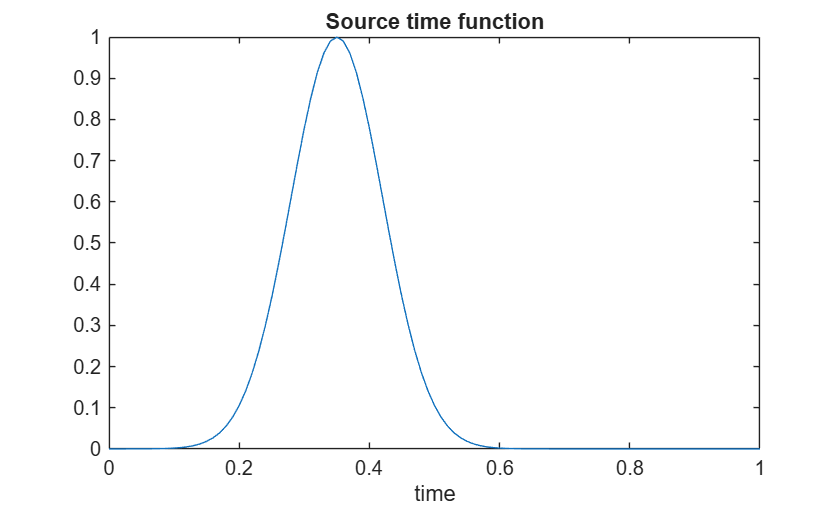

location0 = [0.33,0.43];
tc = 0.35;
s0 = [0,0];
w = @(t) exp(-((t-tc)/0.1).^2);
monopole = MultipoleComponent2D(location0,s0,TargetField="pressure");
mps = MultipoleSrcTerm2D(monopole,w);
spatialOrder = 4; 
source = mps.discretize(gridSp_P,gridSp_Vx,gridSp_Vy,spatialOrder);

figure
plot(t_rcv,w(t_rcv))
xlabel("time")
title("Source time function");

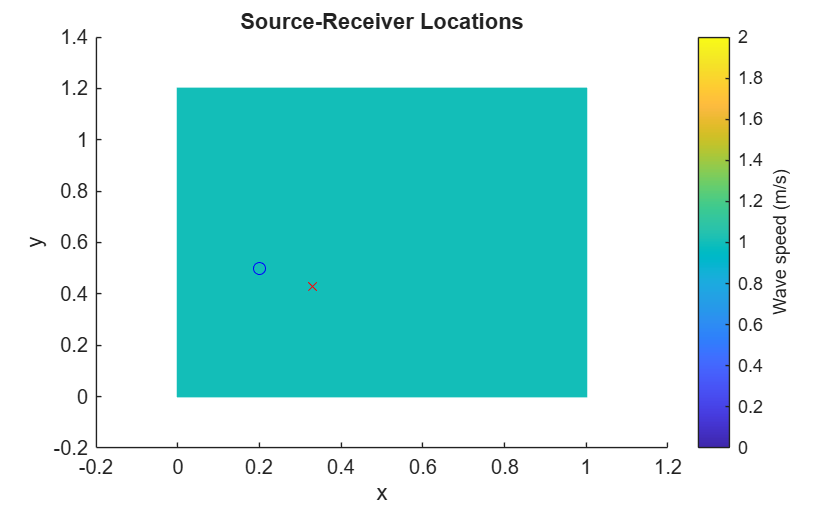

figure
plotAcqGeo(wspeed,mps,gridSp_rcv);
title("Source-Receiver Locations")

Initializing and running solver to compute acoustic data directly.

solver = AcousticSolver2D_PML( ...
    gridSp_P,   t_cmp, ...
    gridSp_rcv, t_rcv, ...
    medium, pml, ...
    SpatialOrder=4);



[P,~,~] = solver.solve(p0,vx0,vy0,Source=source);
data = P.values(:);

## Computing pressure data via convolution

For this test the spatial and time grids are the same as those used to compute the pressure data directly. In practice, more refined grids may be used for the Green's function computation.

% Spatial computational grids and grid spaces
NxG=Nx;
NyG=Ny;

grid_x_primalG = Grid1DUnifPrimal(domain_x,NxG);
grid_y_primalG = Grid1DUnifPrimal(domain_y,NyG);
grid_x_dualG   = Grid1DUnifDual(grid_x_primalG);
grid_y_dualG   = Grid1DUnifDual(grid_y_primalG);

gridSp_PG = GridSpace2D(grid_x_primalG, grid_y_primalG);    %grid space for pressure
gridSp_VxG = GridSpace2D(grid_x_dualG,  grid_y_primalG);    %grid spaces for velocity in x
gridSp_VyG = GridSpace2D(grid_x_primalG,  grid_y_dualG);    %grid spaces for velocity in y
hG = gridSp_PG.h;    %spatial grid sizes, h = [dx,dy]

% Sampling medium parameters to compute max wave speed 
[~,~,~,~,cMaxG] = sampleMedium2D(gridSp_PG,medium);

% Determining computational time grid size
CFL_factor = 0.8;
dt_cmpG = CFL_factor*(6/7)/(cMaxG*sqrt(sum(1./hG.^2))); %CFL condition for 2-4 FDM
Nt_cmpG = ceil(diff(domain_t)/dt_cmpG)+1;
dt_cmpG = diff(domain_t)/(Nt_cmpG-1); %recomputing to ensure time domain divisible by dt

In order to carry out convolutions with the Green's function $G^p$, we will need to extend the Green's function to be defined over $[-T,T]$.

Naive approach

Given that the Green's function is casual, that is, $G^p(x,y,t)=0$ for $t<0$, we could simply compute the Green's function over the same computational time grid as the pressure data, and simply pad by zeros the result time series. There is however an issue with this approach. When discretizing the time Dirac delta function $\delta(t)$, we end up with an acoustic source that is technically not causal. Let $\tilde \delta(t)$ represent said discretization. It turns out that $\tilde \delta(t) =0$ for $t<-\Delta_t$, where $\Delta_t$ is the computational time grid size.

Smarter approach

Since we know $\tilde \delta(t)=0$ for $t<-\Delta_t$, it suffices to set the computational domain to $[-\Delta_t, T]$, and pad the computed Green's function by zeros for the remaining time interval $[-T,-\Delta t)$.

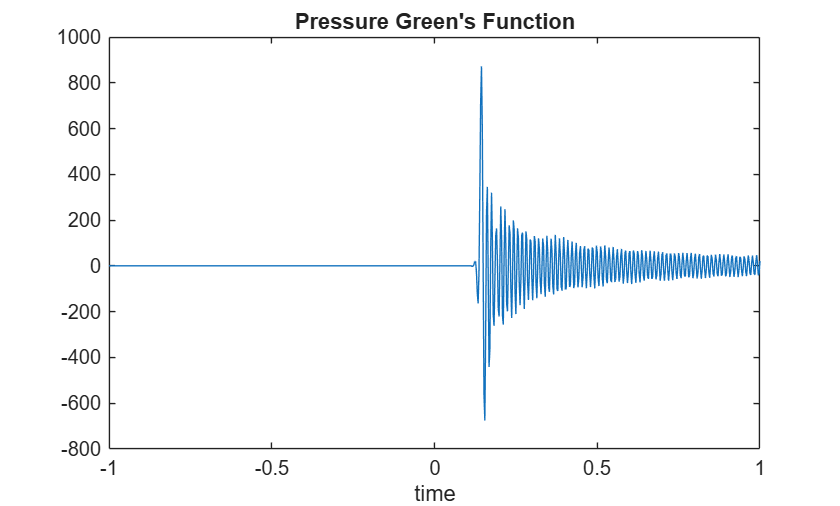

% Computational time points
t_cmpG = 0:dt_cmpG:t_final;
% Green solver times: one step before zero through t_final
t_cmpG_ext = (-1:Nt_cmpG-1)*dt_cmpG;

delta_t = @(t) deltaTime(t,0,dt_cmpG);
monopole = MultipoleComponent2D(location0,s0,TargetField="pressure");
mps_green = MultipoleSrcTerm2D(monopole,delta_t);
source_green = mps_green.discretize(gridSp_PG,gridSp_VxG,gridSp_VyG,spatialOrder);

% Initialize solver for direct data.
% Note that the output time grid is the same as the computational time
% grid.
solver_green = AcousticSolver2D_PML( ...
    gridSp_PG,  t_cmpG_ext, ...
    gridSp_rcv, t_cmpG_ext, ...
    medium, pml, ...
    SpatialOrder=4);

% Running solver
[P_green,~,~] = solver_green.solve(p0,vx0,vy0,Source=source_green);
G_short = P_green.values(:);

% G_short begins at -dt_cmpG
data_green = [zeros(Nt_cmpG-2,1);G_short];

% Full Green grid from -t_final through t_final
t_ext = -t_final:dt_cmpG:t_final;

% Sanity checks
iZero = Nt_cmpG;
assert(numel(data_green) == numel(t_ext))
assert(abs(t_ext(iZero)) < 100*eps)

figure
plot(t_ext,data_green)
xlabel("time")
title("Pressure Green's Function")

Here we implement the discretization of


$$p(x_r,y_r,t) = G^p(x_r,y_r,t)* w(t)$$


by constructing the convolution matrix associated with our Green's function.

It should be noted that this discrete convolution is done the fine computational grid instead of the coarse receiver time grid. Interpolating into the coarser grid is then done after the discrete convolution to minimize interpolation errors.

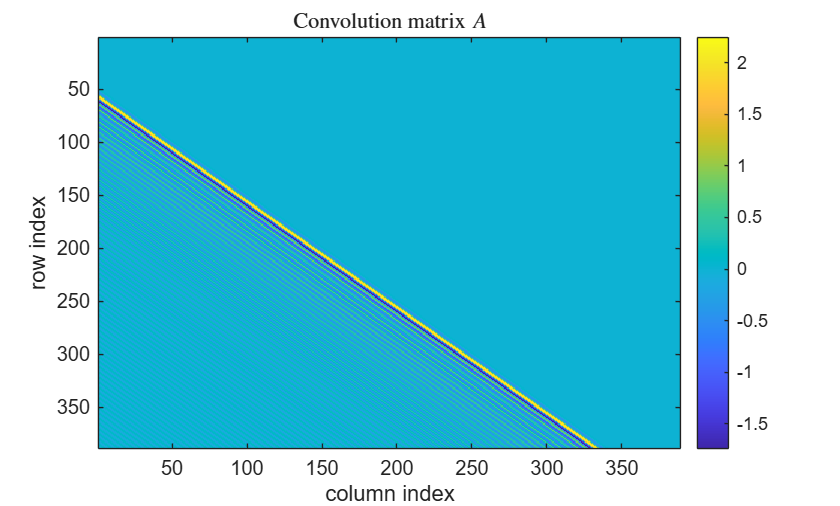

% Constructing convolution matrix
A_row = dt_cmpG*data_green(iZero:-1:1).';
A_col = dt_cmpG*data_green(iZero:end);
A = toeplitz(A_col,A_row);

figure
% spy(F)
imagesc(A)
xlabel('column index')
ylabel('row index')
colorbar
title('Convolution matrix $A$','Interpreter','latex')

% Computing pressure data via convolution
w_data = w(t_cmpG)';
data_alt_cmp = A*w_data;

% Interpolating onto coarser receiver time grid
data_alt = interp1(t_cmpG,data_alt_cmp,t_rcv,'linear').';

We compare the directly and convolution computed pressure data.

relError = norm(data-data_alt)/norm(data);
fprintf("Relative error: %.3e\n",relError)

Relative error: 2.399e-04


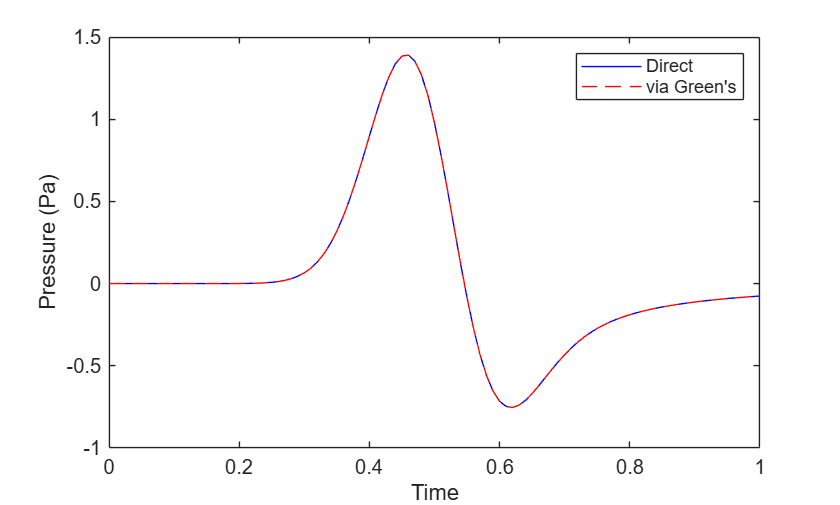


% Plotting both data
figure

plot(t_rcv,data,'-b')
hold on
plot(t_rcv,data_alt,'--r')
hold off

xlabel("Time")
ylabel(P.formattedLabel)
legend("Direct","via Green's")

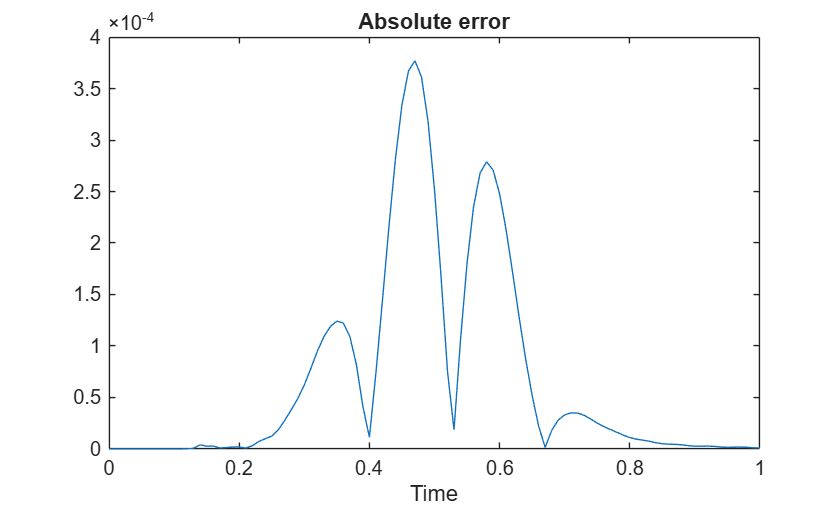

% Plotting error
figure
plot(t_rcv,abs(data-data_alt))
xlabel("Time")
title("Absolute error")

## Conclusions

This demo offers a way to validate the computation of a Green's function in 2 dimensions. 

When computing Green's functions, 

- highly refined grids should be used (in space and time)

- need to take special care when setting up computational time domain (may require zero-padding)

- output time grid should be the same as the computational time grid

- interpolation onto coarser time grid should be done after convolution